ans = "Signal 5: 21:20 Actual moment under Rolls [Nm]"

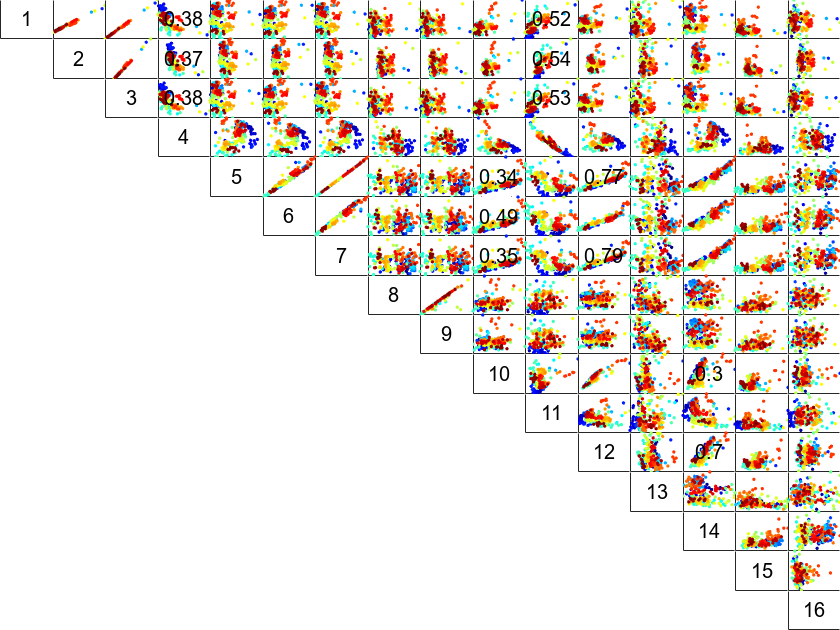

lowerR2 = 0.3;
upperR2 = 0.8;
r2ReducedThreshold = 0.9;
selectedSignal = 5; % 21:20 & Actual moment under Rolls
saveFigures = true;
R2 = fnPlotFeatureVsFeature_Array(featureArray_Standard, lowerR2, upperR2, selectedSignal, FeatureNames_Combined, sensorNames);

disp(num2str(R2, '%.2f  '));

1.00  0.98  1.00  0.38  0.02  0.01  0.02  0.03  0.01  0.25  0.52  0.04  0.05  0.02  0.00  0.00
0.00  1.00  0.99  0.37  0.05  0.00  0.05  0.03  0.00  0.15  0.54  0.01  0.05  0.05  0.01  0.00
0.00  0.00  1.00  0.38  0.03  0.00  0.03  0.03  0.00  0.21  0.53  0.03  0.05  0.03  0.00  0.00
0.00  0.00  0.00  1.00  0.17  0.07  0.16  0.06  0.02  0.12  0.91  0.00  0.06  0.16  0.00  0.00
0.00  0.00  0.00  0.00  1.00  0.95  1.00  0.01  0.00  0.34  0.28  0.77  0.05  0.90  0.13  0.02
0.00  0.00  0.00  0.00  0.00  1.00  0.95  0.00  0.00  0.49  0.13  0.87  0.03  0.85  0.13  0.02
0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.01  0.00  0.35  0.27  0.79  0.05  0.90  0.14  0.02
0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.87  0.02  0.05  0.00  0.02  0.01  0.10  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.01  0.01  0.00  0.11  0.00  0.10  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.06  0.80  0.01  0.30  0.17  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.

## Combination 1

combination = 1;
selectedFeature = 1;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray_Standard,R2, upperR2, lowerR2, r2ReducedThreshold, true);

Sig 4 Sig 11 = 0.91
     1     4    11
     1     4


figure(); hold on;
sensorNames(selectedSignal)%title(sensorNames(selectedSignal));

ans = "21:20 Actual moment under Rolls [Nm]"

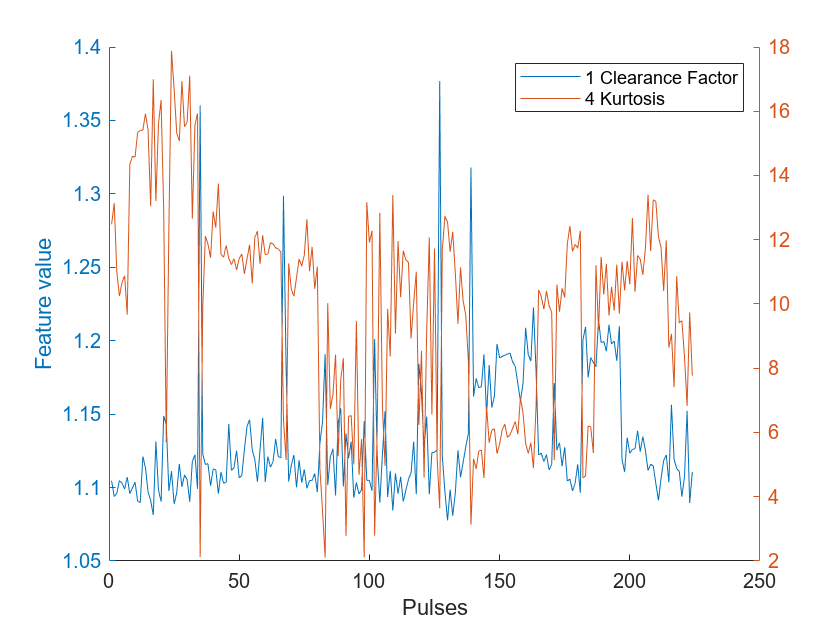

xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [2];
legendAxis = [];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
        ha = plot(selectedFeatureData{i});
        legendAxis = [legendAxis ha];
    else
        yyaxis left;
        hb = plot(selectedFeatureData{i});
        legendAxis = [legendAxis hb];
    end
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
hold off;
legend(legendAxis, leg)

if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature;
    print(filename,'-depsc','-tiff')
end

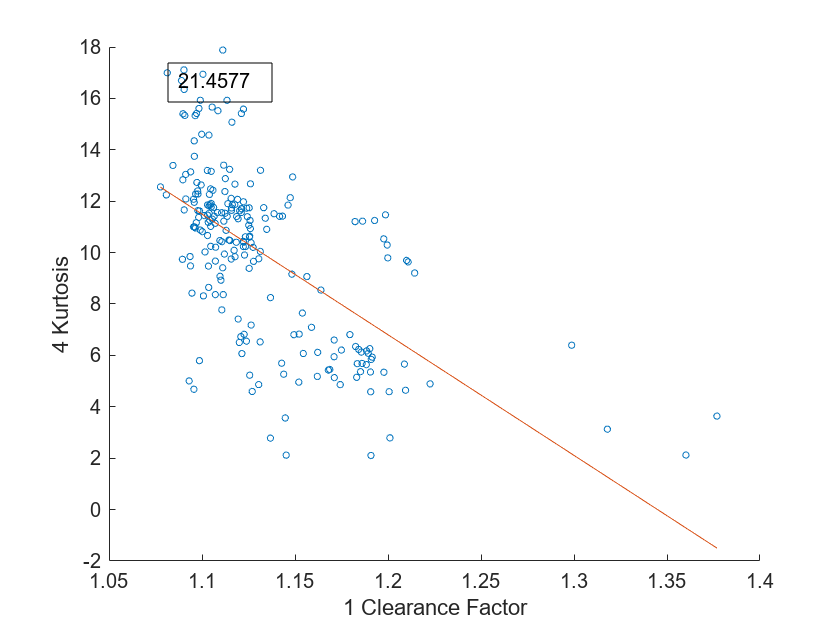

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
linearModelNum = 1;
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                + "Feature" + selectedFeature ...
                + "_Linear" + linearModelNum;
            export_fig(filename, '-eps', '-depsc');
            linearModelNum = linearModelNum + 1;
        end
    end
end

multivariateModelNum = 1;
if numOfSelectedFeatures > 2
    for index1 = 1 : numOfSelectedFeatures
        for index2 = index1+1 : numOfSelectedFeatures
            if selectedFeatureArray(index1) ~= selectedFeature && selectedFeatureArray(index2) ~= selectedFeature            
                Y_est = fnPlotModel3D( ...
                    selectedFeatureData{selectedFeatureIdx}, ...
                    selectedFeatureData{index1}, ...
                    selectedFeatureData{index2}, ...
                    sensorNames(selectedSignal), ...
                    FeatureNames(selectedFeatureArray(selectedFeatureIdx)), ...
                    FeatureNames(selectedFeatureArray(index1)), ...
                    FeatureNames(selectedFeatureArray(index2)));
                if (saveFigures == true)
                    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                        + "Feature" + selectedFeature ...
                        + "_Multivariate" + multivariateModelNum;
                    export_fig(filename, '-eps', '-depsc');
                    multivariateModelNum = multivariateModelNum + 1;
                end
            end
        end
    end
end

## Combination 2

combination = 2;
selectedFeature = 10;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray_Standard,R2, upperR2, lowerR2, r2ReducedThreshold, true);

Sig 5 Sig 6 = 0.95
Sig 5 Sig 7 = 1.00
     5     6     7    10    14
     5    10    14


figure(); hold on;
sensorNames(selectedSignal)%title(sensorNames(selectedSignal));

ans = "21:20 Actual moment under Rolls [Nm]"

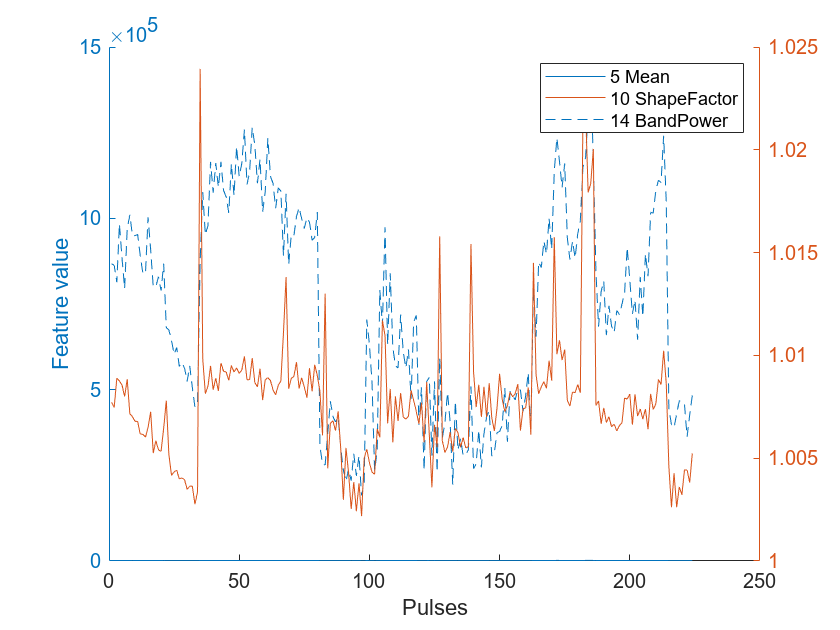

xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [2];
legendAxis = [];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
        ha = plot(selectedFeatureData{i});
        legendAxis = [legendAxis ha];
    else
        yyaxis left;
        hb = plot(selectedFeatureData{i});
        legendAxis = [legendAxis hb];
    end
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
hold off;
legend(legendAxis, leg)

if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature;
    print(filename,'-depsc','-tiff')
end

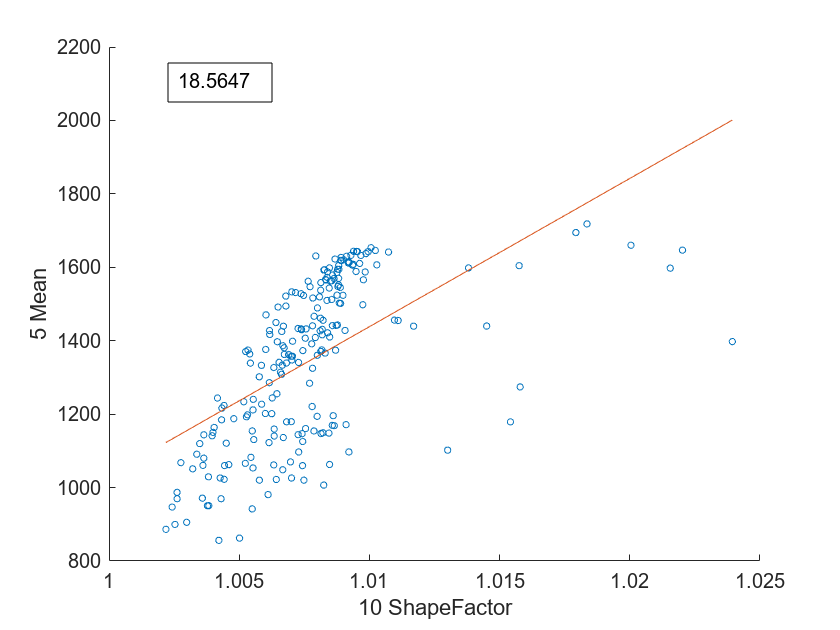

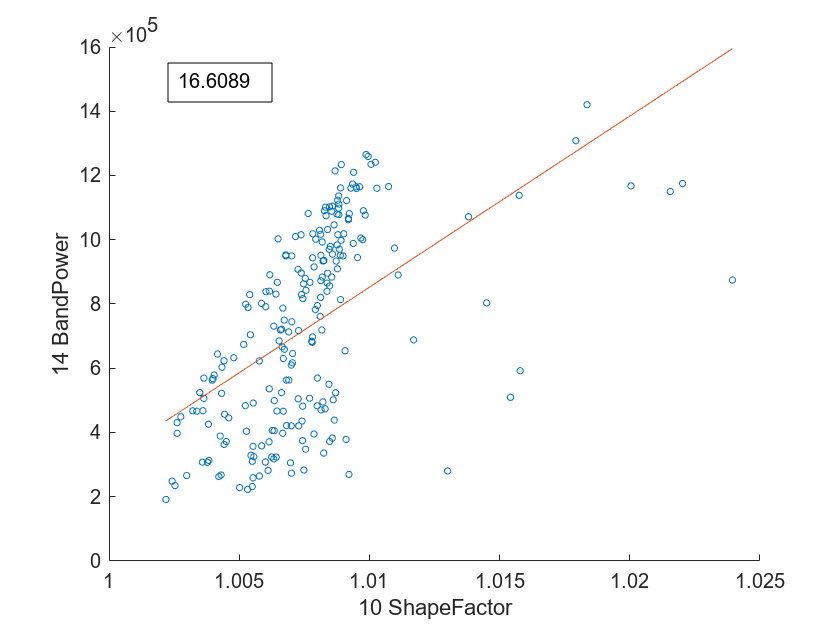

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
linearModelNum = 1;
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                + "Feature" + selectedFeature ...
                + "_Linear" + linearModelNum;
            export_fig(filename, '-eps', '-depsc');
            linearModelNum = linearModelNum + 1;
        end
    end
end

## Combination 3

combination = 3;
selectedFeature = 12;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray_Standard,R2, upperR2, lowerR2, r2ReducedThreshold, true);

Sig 5 Sig 7 = 1.00
     5     7    12    14
     5    12    14


figure(); hold on;
sensorNames(selectedSignal)%title(sensorNames(selectedSignal));

ans = "21:20 Actual moment under Rolls [Nm]"

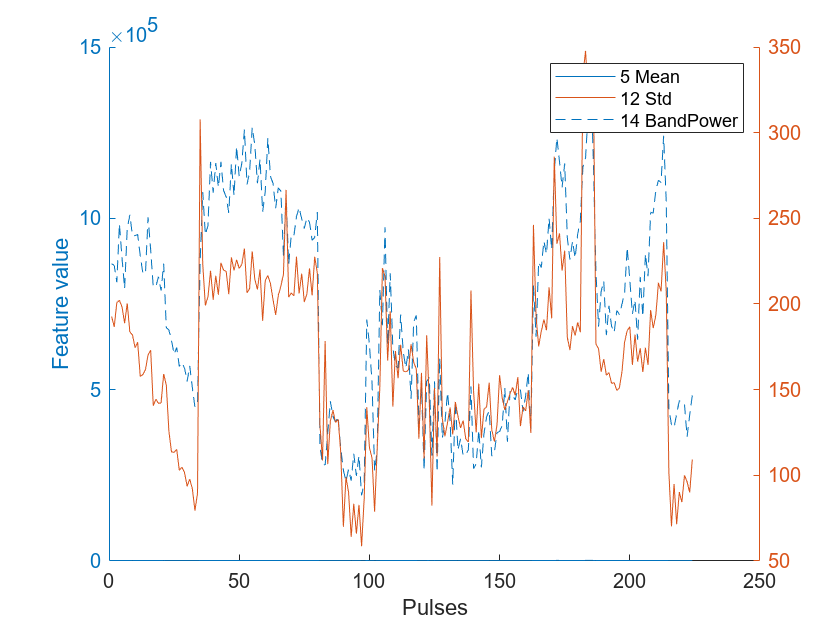

xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [2];
legendAxis = [];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
        ha = plot(selectedFeatureData{i});
        legendAxis = [legendAxis ha];
    else
        yyaxis left;
        hb = plot(selectedFeatureData{i});
        legendAxis = [legendAxis hb];
    end
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
hold off;
legend(legendAxis, leg)

if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature;
    print(filename,'-depsc','-tiff')
end

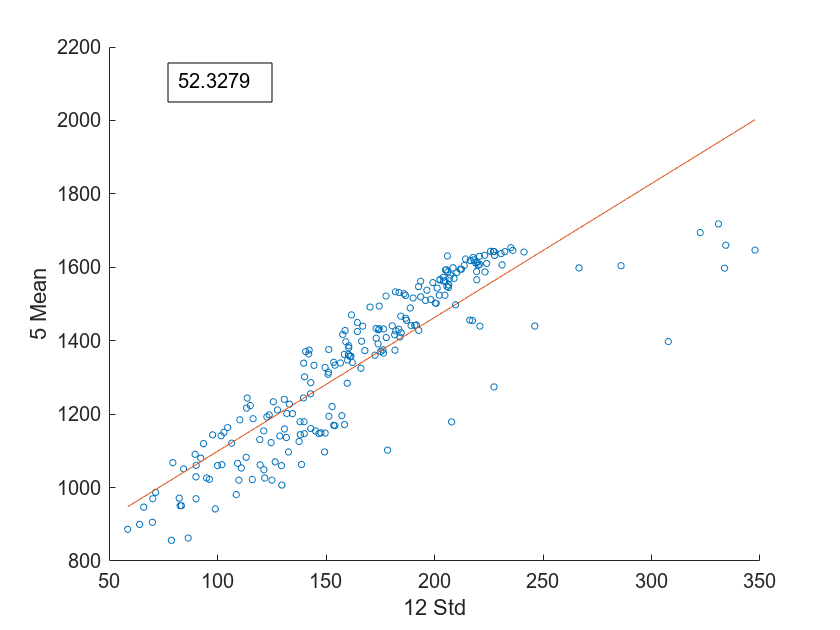

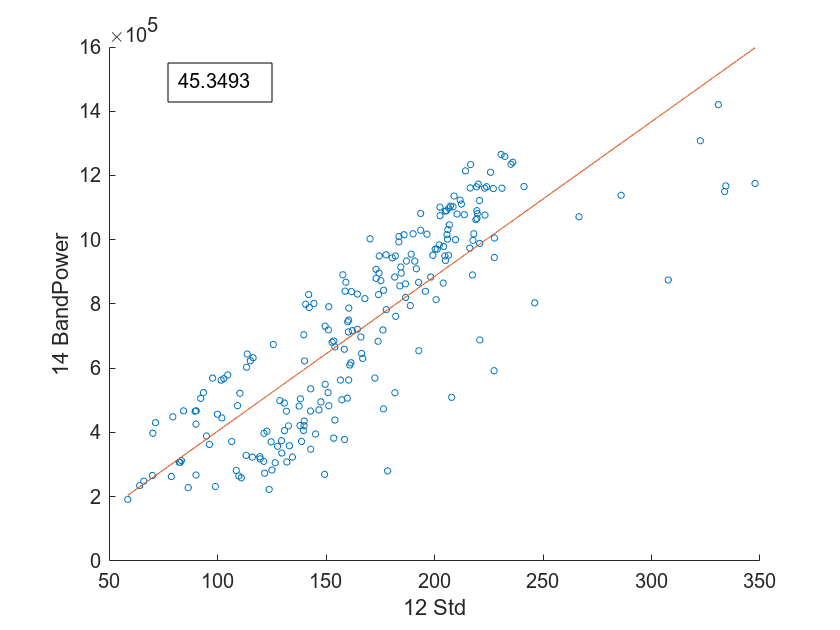

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
linearModelNum = 1;
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                + "Feature" + selectedFeature ...
                + "_Linear" + linearModelNum;
            export_fig(filename, '-eps', '-depsc');
            linearModelNum = linearModelNum + 1;
        end
    end
end

## Combination 4

combination = 4;
selectedFeature = 14;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray_Standard,R2, upperR2, lowerR2, r2ReducedThreshold, true);

    10    12    14
    10    12    14


figure(); hold on;
sensorNames(selectedSignal)%title(sensorNames(selectedSignal));

ans = "21:20 Actual moment under Rolls [Nm]"

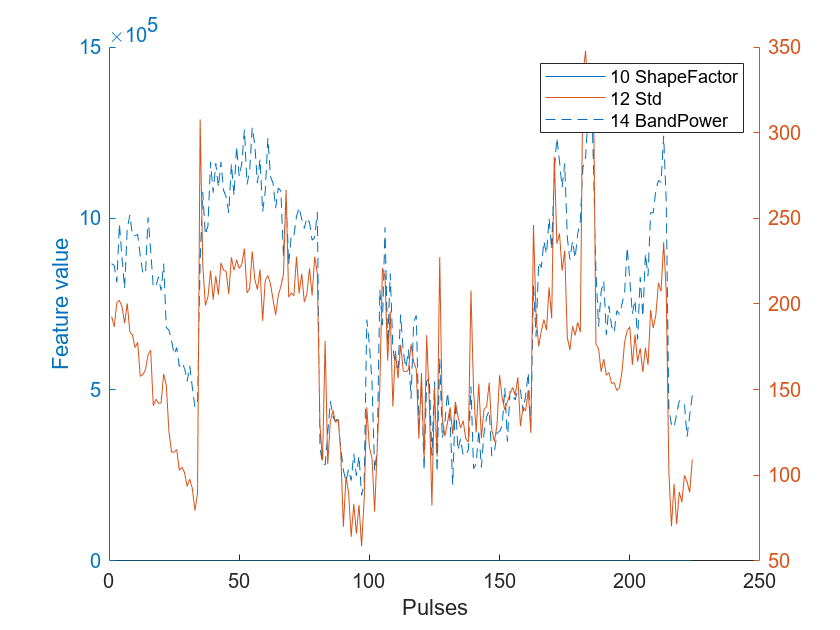

xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [2];
legendAxis = [];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
        ha = plot(selectedFeatureData{i});
        legendAxis = [legendAxis ha];
    else
        yyaxis left;
        hb = plot(selectedFeatureData{i});
        legendAxis = [legendAxis hb];
    end
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
hold off;
legend(legendAxis, leg)

if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature;
    print(filename,'-depsc','-tiff')
end

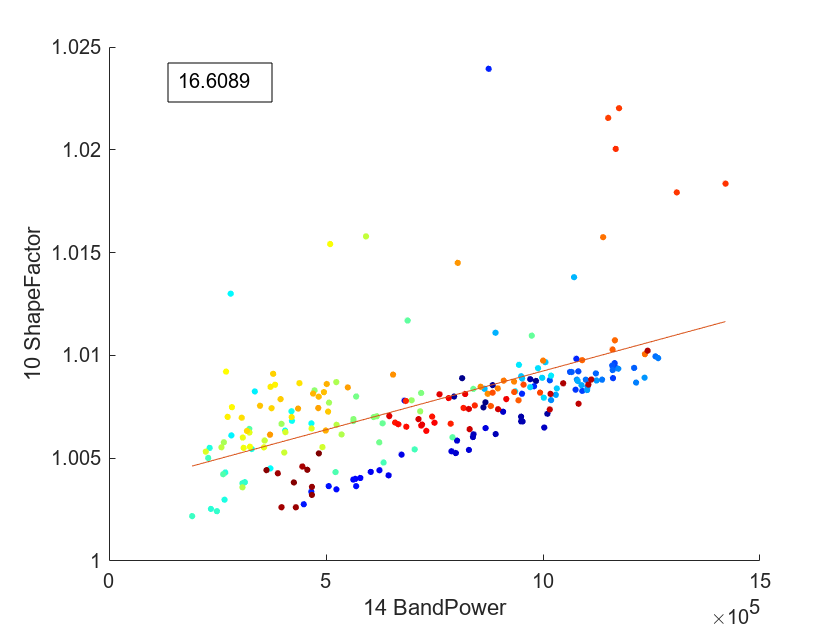

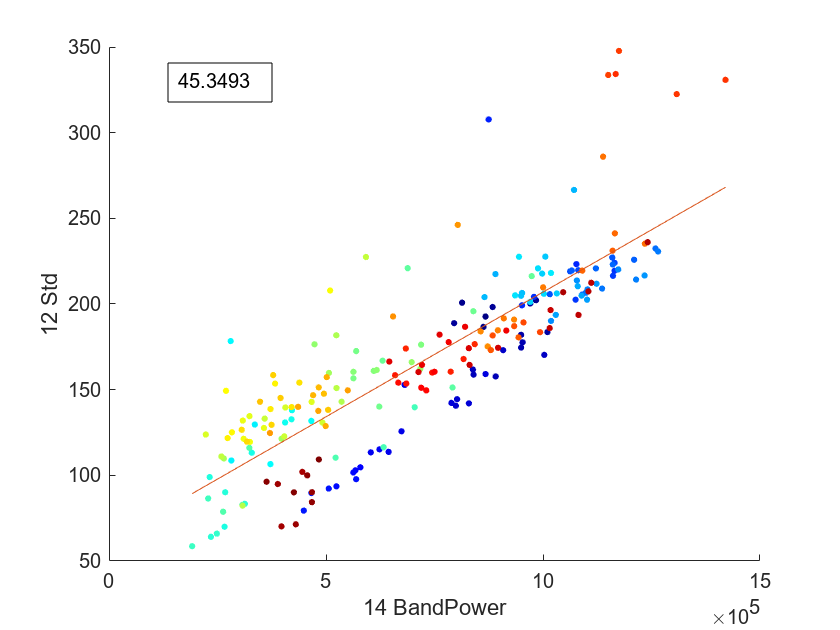

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
linearModelNum = 1;
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                + "Feature" + selectedFeature ...
                + "_Linear" + linearModelNum;
            export_fig(filename, '-eps', '-depsc');
            linearModelNum = linearModelNum + 1;
        end
    end
end